electrodes = electrodes(:,[3,14,16,18]);

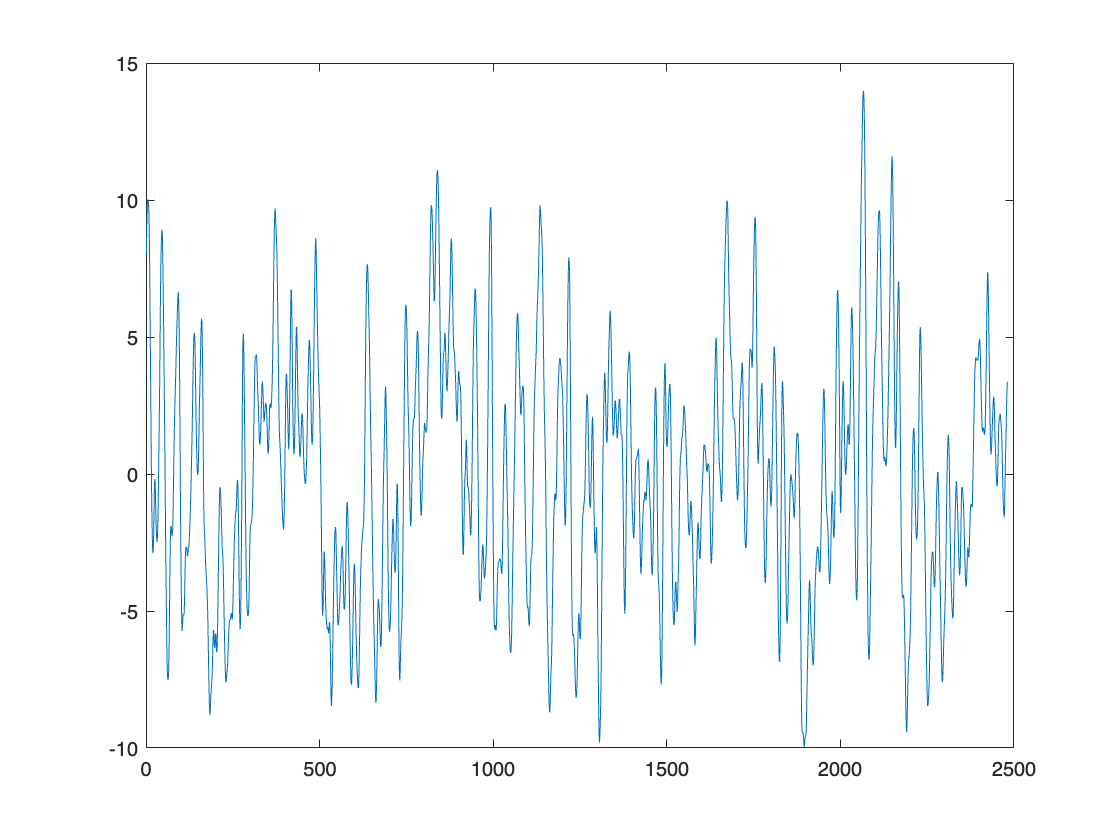

plot(electrodes(9600:12080,1))

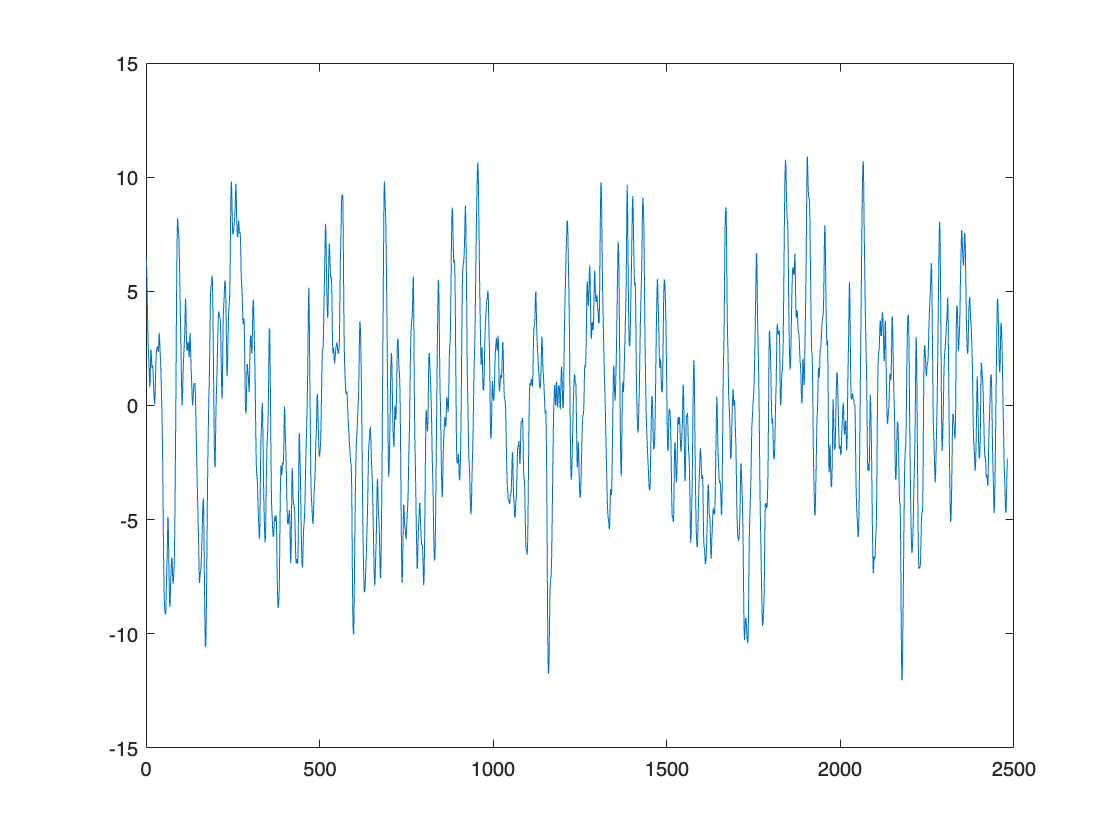

plot(electrodes(9600:12080,2))

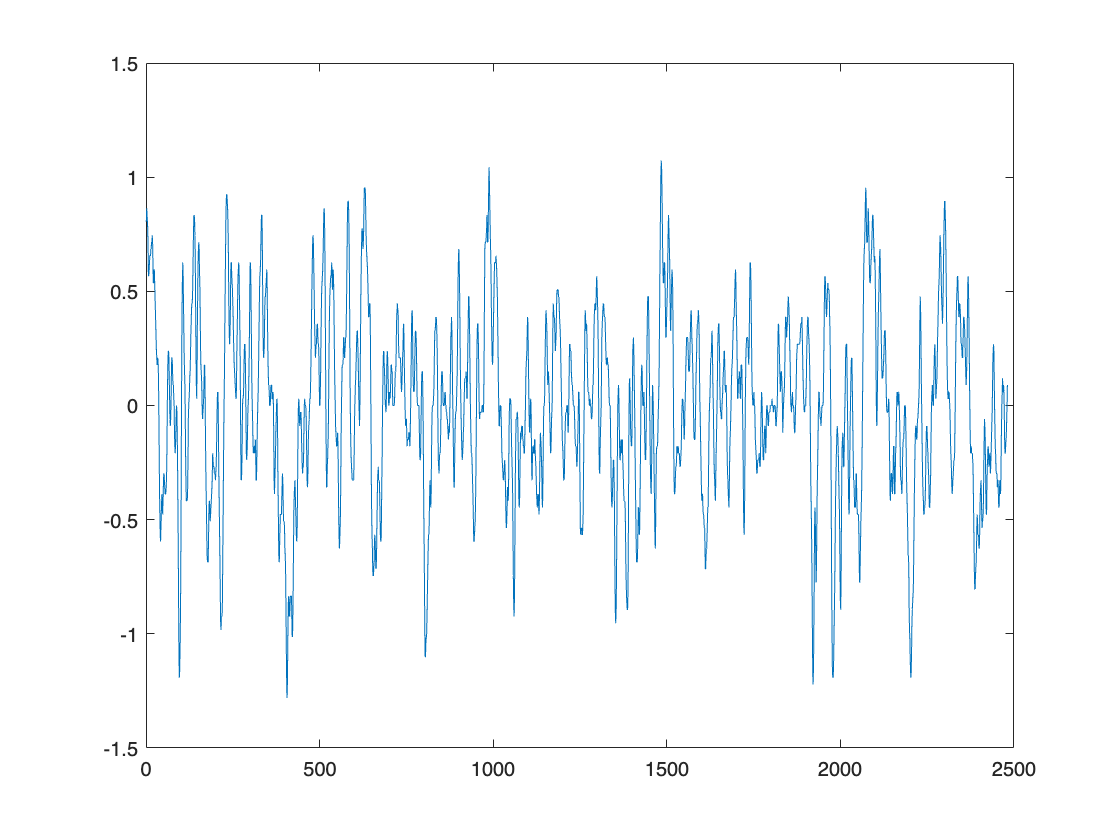

plot(electrodes(9600:12080,3))

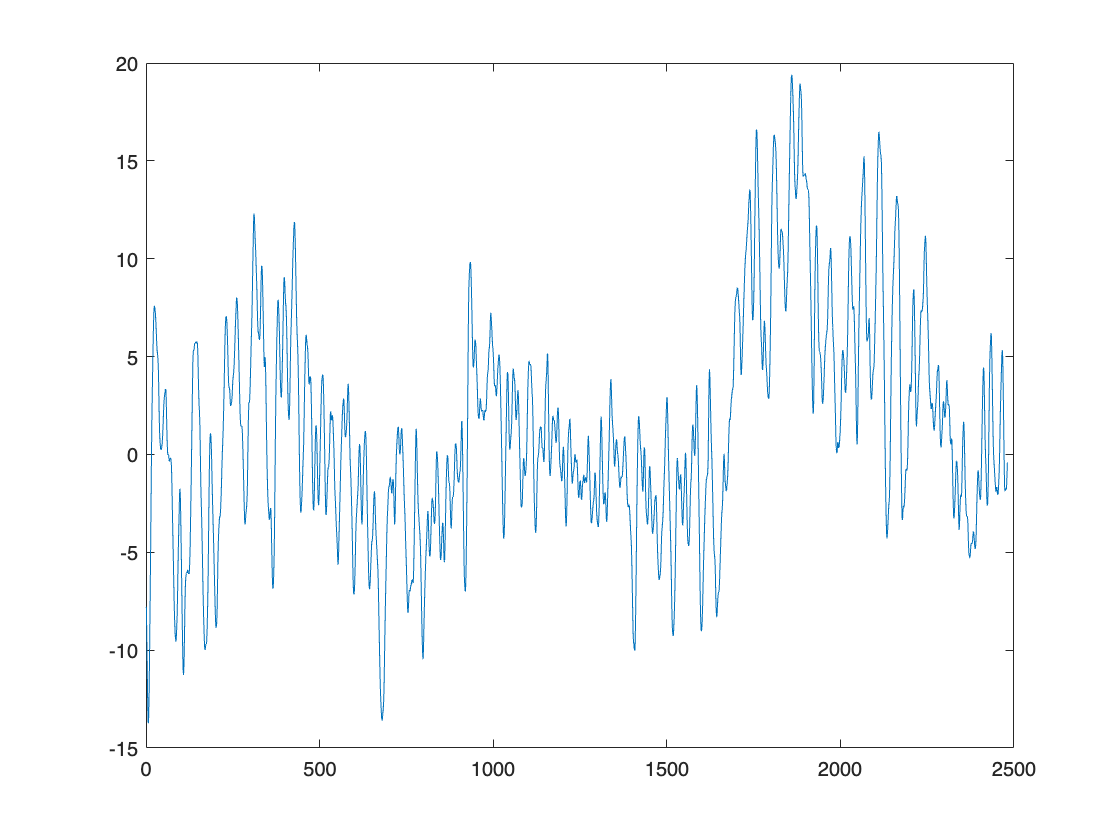

plot(electrodes(9600:12080,4))

electrodes(:,1);
elec = [electrodes(:,1)',electrodes(:,2)',electrodes(:,3)',electrodes(:,4)'];

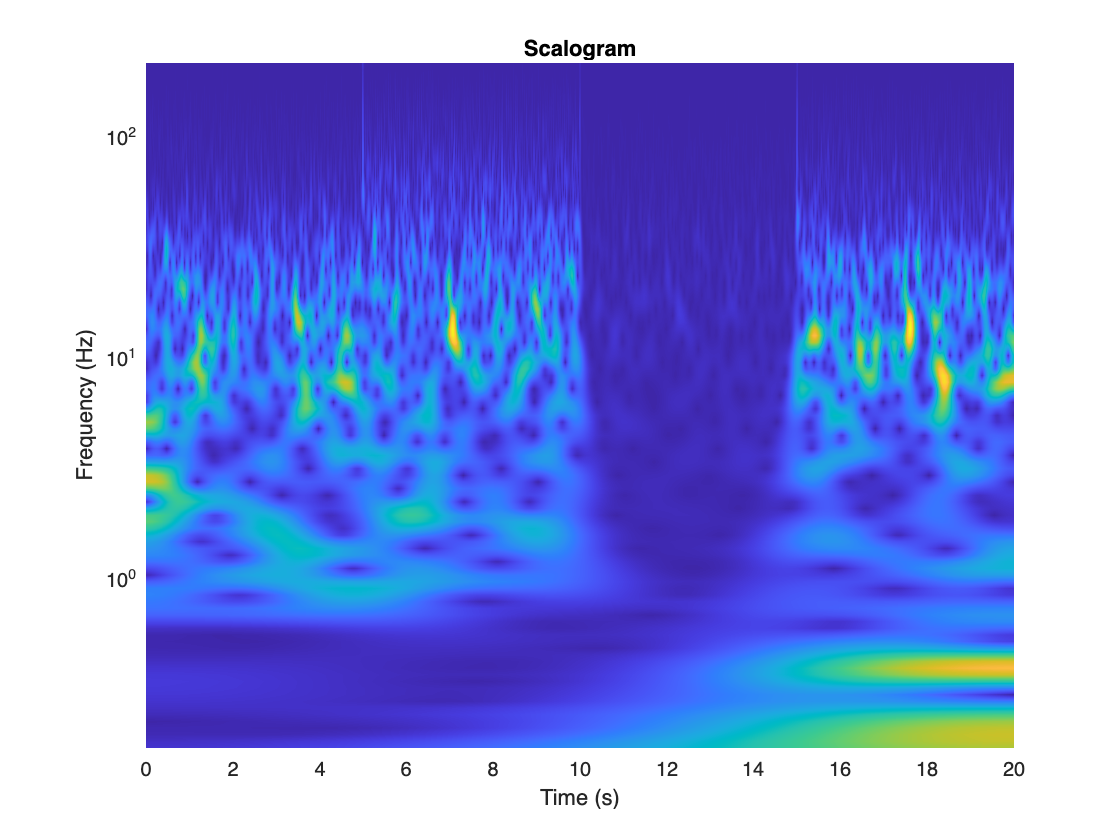

% Concaténation des signaux des différentes électrodes
sig = [electrodes(23100:25600,1);...
    electrodes(23100:25600,2);...
    electrodes(23100:25600,3);...
    electrodes(23100:25600,4)];
% Transformée en ondelettes du signal
fb = cwtfilterbank(signallength = length(sig),...
    samplingfrequency=500, ...
    wavelet="Morse");
[cfs,frq] = wt(fb,sig);
% 
t = (0:(length(sig)-1))/500;
h = figure;
pcolor(t,frq,abs(cfs));
set(gca,'yscale','log');shading interp;axis tight;
title('Scalogram');xlabel('Time (s)');ylabel('Frequency (Hz)');

%set(h, 'Units', 'pixels', 'Position', [0 0 224 224]);